Q1 d

First, we define the system variables, equations, and parameters:

beta = 0.95;
sigma = 2;
alpha = 0.36;
delta = 0.025;
z = 1;
rho = 0.95;

syms c k;

u = (c^(1-sigma))/(1-sigma);
f = z*(k^alpha)+(1-delta)*k;

%the derivatives we need
uc = diff(u,c);
ucc = diff(u,c,2);
fz = k^alpha;
fkz = alpha*(k^(alpha-1));
fkk = diff(f,k,2);

%Steady State Values:
eqn = diff(f,k) == 1/beta;
k_s = vpasolve(eqn,k)

$$k\_s = 10.991010612281837809342964723909$$

c_s = k_s^alpha - delta*k_s

$$c\_s = 2.095362257078291886459535964909$$


%Now substitute the ss values into the derivatives:
u_c = subs(uc,c,c_s);
u_cc = subs(ucc,c,c_s);
f_z = subs(fz,k,k_s);
f_kz = subs(fkz,k,k_s);
f_kk = subs(fkk,k,k_s);

%Now define matrix A:
A = [1/beta -1;-u_c*f_kk/u_cc 1+beta*u_c*f_kk/u_cc]

$$A = \left(\begin{array}{cc} \frac{20}{19} & -1\\ -0.0047359803016312711603570329332102 & 1.0044991812865497076023391812865 \end{array}\right)$$


%Now find Eigenvalues and vectors of A:
[V,D] = eig(A)

$$V = \left(\begin{array}{cc} 0.99880950726738043663087200887773 & 0.99533117943130100875138398059295\\ -0.048780817872322587197637358527353 & 0.096518616089826296914068917348299 \end{array}\right)$$

$$D = \left(\begin{array}{cc} 1.1014705392469964107450895252951 & 0\\ 0 & 0.95566022098692171790988123493877 \end{array}\right)$$


%Sort by eigenvalue ascending:
[d,ind] = sort(diag(D));
Ds = D(ind,ind)

$$Ds = \left(\begin{array}{cc} 0.95566022098692171790988123493877 & 0\\ 0 & 1.1014705392469964107450895252951 \end{array}\right)$$

Vs = V(:,ind)

$$Vs = \left(\begin{array}{cc} 0.99533117943130100875138398059295 & 0.99880950726738043663087200887773\\ 0.096518616089826296914068917348299 & -0.048780817872322587197637358527353 \end{array}\right)$$

Q1 e

We now find V^-1 and C:

V_l = inv(Vs)

$$V\_l = \left(\begin{array}{cc} 0.33651973884488115429524864563708 & 6.8903952250483197190830691996245\\ 0.66584409398856208040992405550238 & -6.866399604924072758927307814772 \end{array}\right)$$


B = [f_z; -beta*u_c*(f_kk*f_z+f_kz*rho)/u_cc]

$$B = \left(\begin{array}{c} 2.3701375223853378316931100830067\\ 0.062739480681008511979749589016554 \end{array}\right)$$


C = V_l*B

$$C = \left(\begin{array}{c} 1.2298978781659999011258042981531\\ 1.1473477258597422030442101525853 \end{array}\right)$$

Now for the values in the equation:

a_1 = -V_l(2,1)/V_l(2,2)

$$a\_1 = 0.096971357960446703142750344008595$$

a_2 = -C(2,1)/((Ds(2,2)-rho)*V_l(2,2))

$$a\_2 = 1.1031582395387806613861903388275$$


b_1 = 1/beta+V_l(2,1)/V_l(2,2)

$$b\_1 = 0.95566022098692171790988123493877$$

b_2 = f_z+C(2,1)/((Ds(2,2)-rho)*V_l(2,2))

$$b\_2 = 1.2669792828465571703069197441792$$

Q1 f

Set policy function

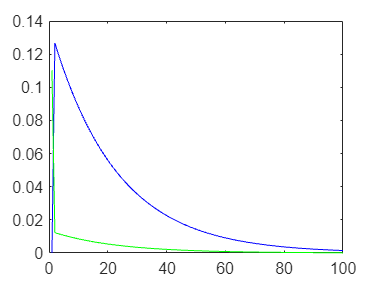

syms k_t z_t
C = a_1*k_t+a_2*z_t;
K = b_1*k_t+b_2*z_t;

%Now plot the time path for 100 period:
T=100;
%First, set the shocks and initial reaction in capital as 0:
z = zeros(T,1);
k = zeros(T,1);
c = zeros(T,1);

z(1) = 0.1;
k(1) = 0;

%Then set the dynamic policy iteration:
for t=1:T-1
    c(t) = subs(C, {k_t z_t}, {k(t) z(t)});
    k(t+1) = subs(K,{k_t z_t},{k(t) z(t)});
end

%Ploting k as blue line, c as green line
g1 = plot([1:T],k,'b', [1:T],c,'g');


% We see a much smoother consumption. 
% This may suggest our savings is really good at dampening shocks.

Q1 h

Starting Dynare (version 5.5).
Calling Dynare with arguments: none
Starting preprocessing of the model file ...
Found 3 equation(s).
Evaluating expressions...done
Computing static model derivatives (order 1).
Computing dynamic model derivatives (order 1).
Processing outputs ...
done
Preprocessing completed.


STEADY-STATE RESULTS:

k 		 10.991
c 		 2.09536
z 		 1

EIGENVALUES:
         Modulus             Real        Imaginary

            0.95             0.95                0
          0.9557           0.9557                0
           1.101            1.101                0
        1.25e+18         1.25e+18                0


There are 2 eigenvalue(s) larger than 1 in modulus 
for 2 forward-looking variable(s)

The rank condition is verified.


MODEL SUMMARY

  Number of variables:         3
  Number of stochastic shocks: 1
  Number of state variables:   2
  Number of jumpers:           2
  Number of static variables:  0


MATRIX OF COVARIANCE OF EXOGENOUS SHOCKS
Variables         

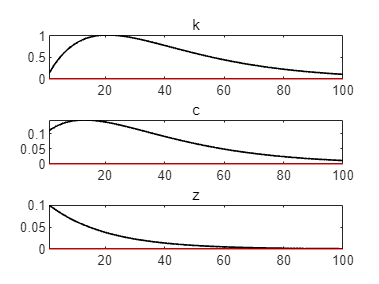

Total computing time : 0h00m07s


%with dynare
dynare model1f.mod;